# WLAN MAC Basics - Adding QoS Traffic + PCAP Basics

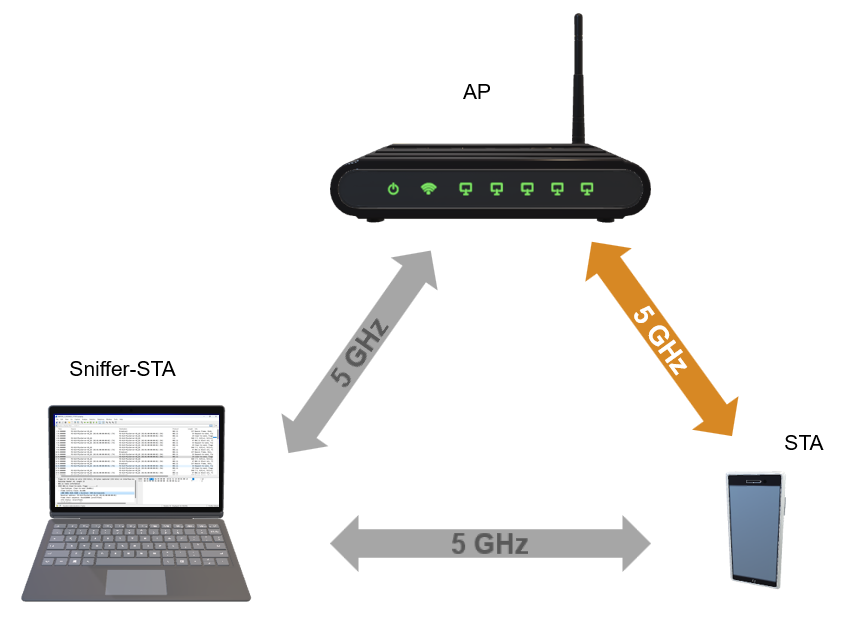

WLAN Network with one AP, one STA, and a Sniffer STA 

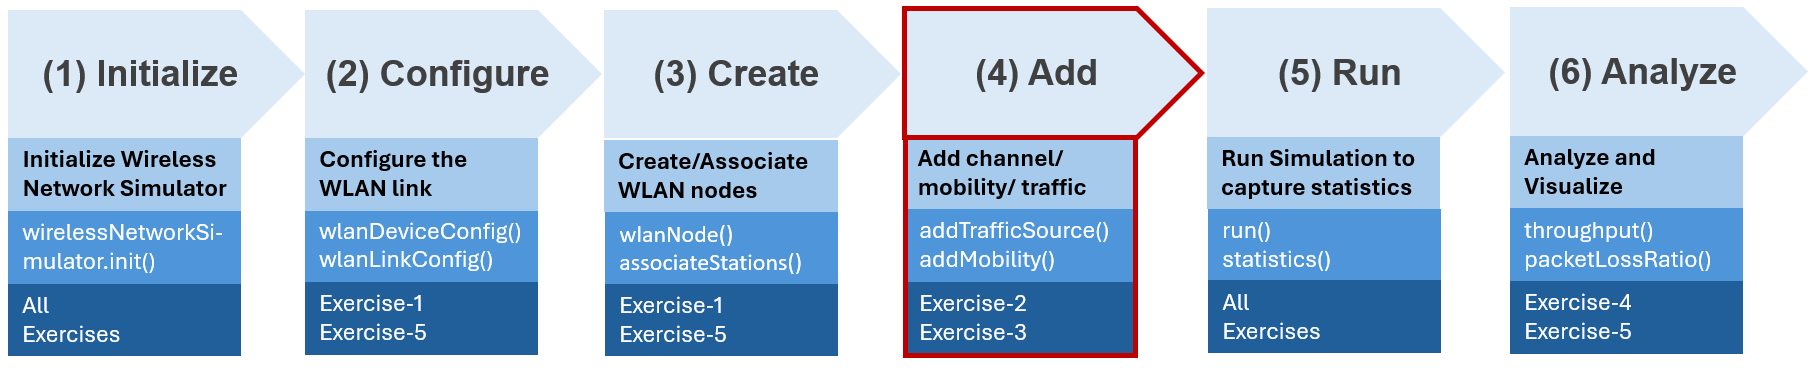

Workflow to perform WLAN Network Modeling 

Copyright 2024-2025 The MathWorks, Inc

### Cleanup

clear;
format shortEng;
% Set seed of random number generator for reproducible results
rng(1,"combRecursive");
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows

## **You need to switch trafficType to QoS_traffic for tasks **

trafficType = "QoS_Traffic"

trafficType = "QoS_Traffic"

### General Settings

bandwidth    = 20e6;
band         = 5;
channel      = 36;
fc           = wlanChannelFrequency(channel,band);

TU              = 1024e-6;
simulationTime  = 100*TU;

### Geography

APPosition  = [0,0,0];
STAPosition = [5,5,0];

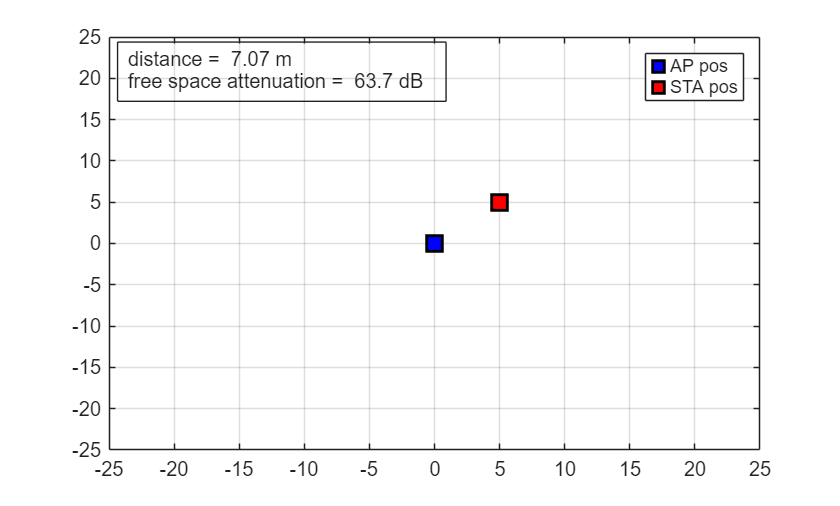

plotStations(APPosition, STAPosition, fc);

#### Create a wirelessNetworkSimulator instance

networkSimulator = wirelessNetworkSimulator.init;

### Create AP

- 802.11n

- beacon sent each 10x TU (1024us)

- AP is located at [0, 0, 0]

- AP transmits 0 dBm 

APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower", 0, ...
    "TransmitGain", 0.0, ...
    "MCS",2, ...
    "BeaconInterval",10, ...
    "InitialBeaconOffset",0, ...
    "AggregateHTMPDU",false);

AP = wlanNode(...
    "Name","AP",...
    "Position",APPosition, ...
    "DeviceConfig",APCfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Create STA

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ...
    "MCS",2, ...
    "ReceiveGain",0);

STA = wlanNode(...
    "Name","STA",...
    "Position",STAPosition, ...
    "DeviceConfig",STACfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

## Create a "sniffer" node

-  Passive node listening to all traffic

- "Concatenate" traffic from AP and STA in a single file

-  Sniffer is not associated with the AP but it is part of the network  

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth,...
    "TransmitPower",0, ...
    "MCS",2, ...
    "ReceiveGain",0);

SNIFFER = wlanNode(...
    "Name","SNIFFER",...
    "Position",STAPosition, ...
    "DeviceConfig",STACfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Associate AP with STA

associateStations(AP,STA,"FullBufferTraffic","off");

# Task #1/2 Configure a traffic model 

Time: 0.000267 s - Generated a periodic packet of size 512 bytes
Time: 0.000533 s - Generated a periodic packet of size 512 bytes
Time: 0.000800 s - Generated a periodic packet of size 512 bytes
Time: 0.001067 s - Generated a periodic packet of size 512 bytes
Time: 0.001333 s - Generated a periodic packet of size 512 bytes
Time: 0.001600 s - Generated a periodic packet of size 512 bytes
Time: 0.001867 s - Generated a periodic packet of size 512 bytes
Time: 0.002133 s - Generated a periodic packet of size 512 bytes
Time: 0.002400 s - Generated a periodic packet of size 512 bytes
Time: 0.002667 s - Generated a periodic packet of size 512 bytes
Time: 0.002933 s - Generated a periodic packet of size 512 bytes
Time: 0.003200 s - Generated a periodic packet of size 512 bytes
Time: 0.003467 s - Generated a periodic packet of size 512 bytes
Time: 0.003733 s - Generated a periodic packet of size 512 bytes
Time: 0.004000 s - Generated a periodic packet of size 512 bytes
Time: 0.004267 s - Genera

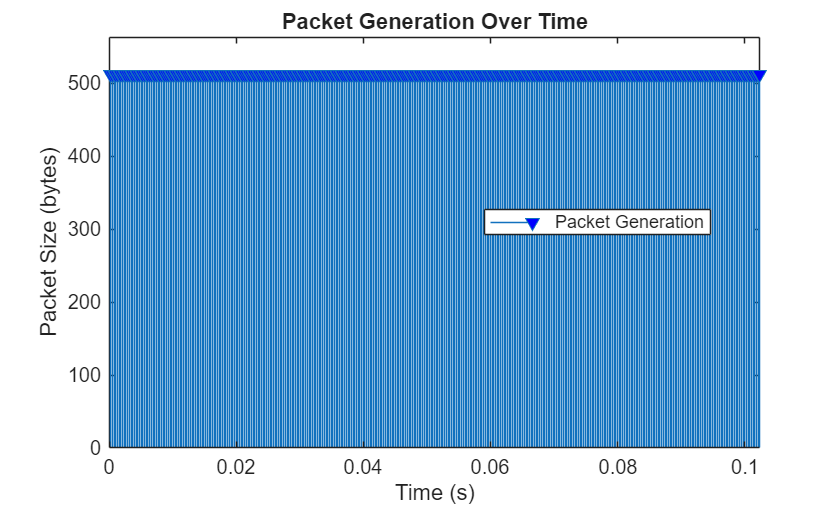

if (strcmp(trafficType, "QoS_Traffic"))

        % Define traffic type

        % Use networkTrafficOnOff() function to configure QoS Traffic
        % Write configuration in a variable named "trafficCfg"
        % Hint: Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.
        % Note : use the following values to start with
        % onTime = inf
        % OffTime = 0
        % DataRate = 1024*1 kpbs
        % PacketSize = 512
        % Define application data for an easy visualizatoin in Wireshark

        % <enter code below>
        trafficCfg = networkTrafficOnOff(...
            "OnTime", inf,...
            "OffTime", 0, ...
            "DataRate",1024*15, ...%kbps
            "PacketSize",512, ...
            "ApplicationData",uint8(0:1:255)',...
            "GeneratePacket",true);


        % Plot traffic pattern 
        plotTrafficPattern(simulationTime,trafficCfg)

# Task #2/2 Integrate a traffic model into AP 

#### Specify a priority level 0 for the generated traffic 

        % Add traffic from source to destination
        % Use addTrafficSource() function to add the traffic to simulation
        % Source is "AP",traffic configuration is "trafficCfg", Destination is "STA"
        % "DestinationNode",STA
        % "AccessCategory",0
        % Hint: Click the link below and see the "Syntax" section.

### [Help on adding traffic source to a node ](https://www.mathworks.com/help/wlan/ref/wlannode.addtrafficsource.html)

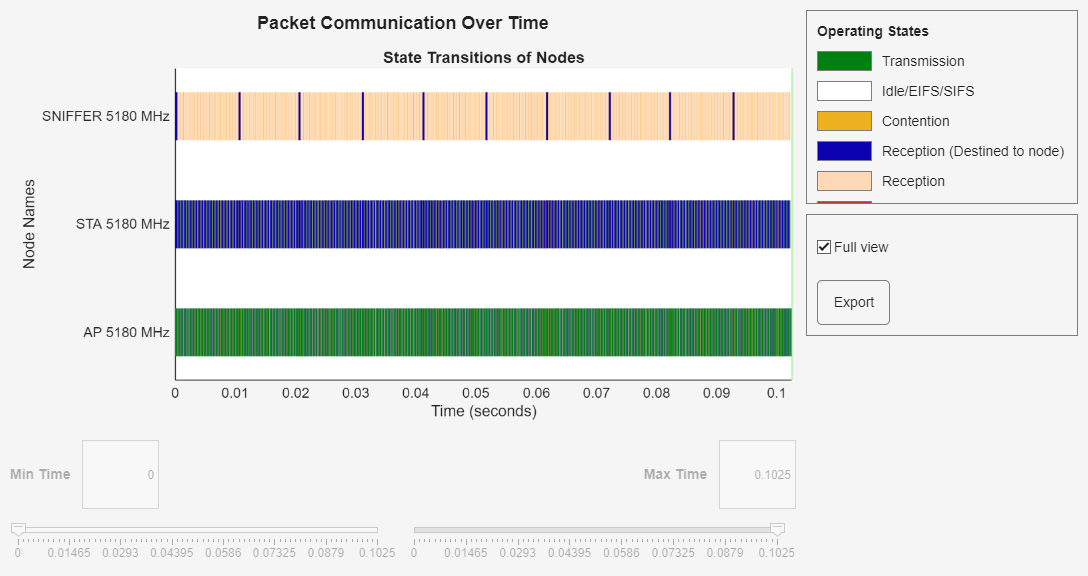

        % <enter code below>

        addTrafficSource(AP, ...
            trafficCfg, ...
            "DestinationNode", STA, ...
            "AccessCategory",2)

#### Create another traffic model 

        % Create traffic configuration 
        trafficCfg_1 = networkTrafficOnOff(...
            "OnTime", inf,...
            "OffTime", 0, ...
            "DataRate",1024*15, ...%kbps
            "PacketSize",513, ...
            "ApplicationData",uint8(0:1:255)',...
            "GeneratePacket",true);

**Add the traffic to the AP and specify AccessCategory 3 **

        % Add traffic wit AccessCategory 3 

ans =      0.0000e+000


ans =      0.0000e+000


ans =     26.0000e+000


ans =    179.0000e+000


        addTrafficSource(AP, ...
            trafficCfg_1, ...
            "DestinationNode",STA, ...
            "AccessCategory",3)
end

### Wireshark shows packet priority  

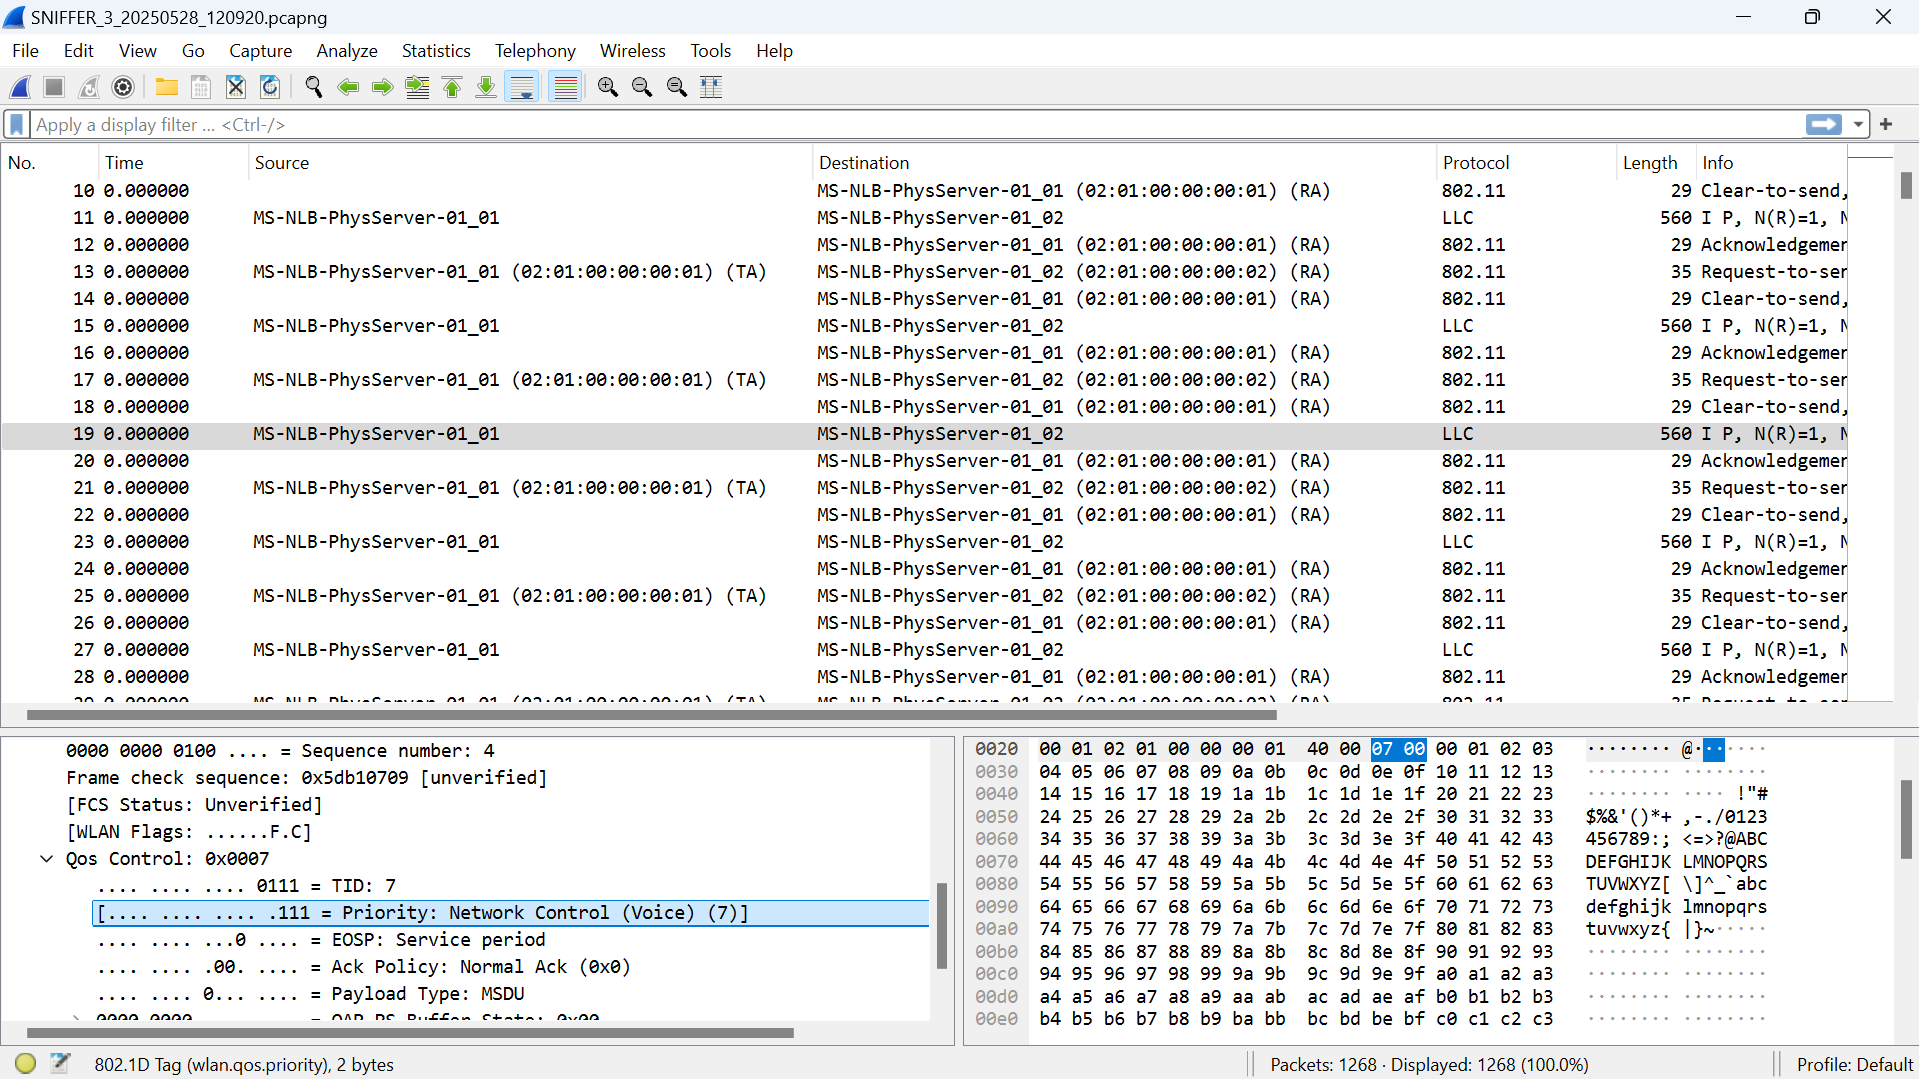

### Create PCAP Capture using the hExportWLANPackets helper Function

- helper functions are early implementations of features that will be fully implemented in the product in future releases

- Provide access to most requested feaures as early as possible

- Gather feedback from early-adopters to help finalize the API

nodes = [AP, STA, SNIFFER];
capturePacketsObj = hExportWLANPackets(nodes, 'pcapng', true);

#### Enable packet visualization

enablePacketVisualization = true; 
if enablePacketVisualization
    packetVisObj = hPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=false);
end

#### Add channel model to the simulator

channelModel = "TGAX";
if strcmp(channelModel,"TGAX")
    channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
    addChannelModel(networkSimulator,channel.ChannelFcn);
end

#### Run the simulation

addNodes(networkSimulator,{AP, STA, SNIFFER})
run (networkSimulator,simulationTime)

### Visualize Results and Statistics

% Navigate to the <Data> folder
% Open SNIFFER PCAP file in Wireshark
% Beacons only (part1), Beacons + traffic (part2)

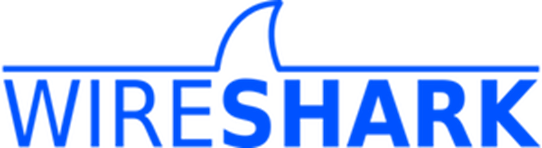

APStatistics  = statistics(AP,"all");
STAStatistics = statistics(STA);

% Use this section to analyze consistency of the data generated in the
% simulation and its visualiation in Wireshark


APStatistics.MAC.AccessCategories.TransmittedDataFrames
delete(capturePacketsObj.PCAPObjList);

**Suggested Experiment:**

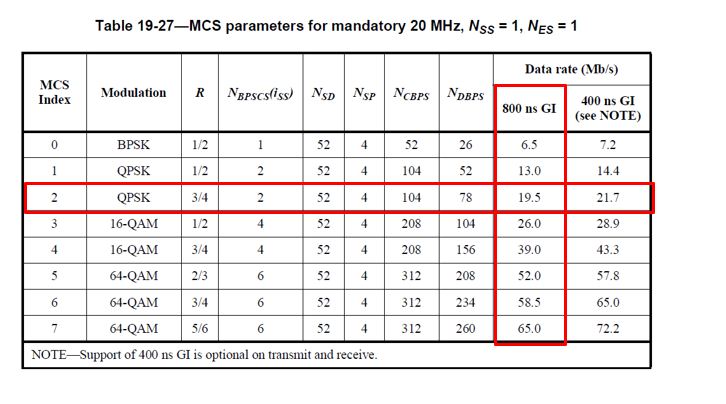

**Based on our current configuration, our link capacity or max data rate is 19.5 Mbps.**

- For downlink traffic, set the data rate of both `trafficCfg` and `trafficCfg_1` to 15 Mbps.

- Visualize the statistics for transmitted packets in each access category.

- Open the corresponding packet captures in Wireshark to examine the traffic in detail.

- Increase the `AccessCategory` in `trafficCfg` from 0 to 2, and repeat Steps 1 to 3.

[**https://www.mathworks.com/help//releases/R2021a/wlan/ug/802-11-mac-qos-traffic-scheduling.html**](https://www.mathworks.com/help//releases/R2021a/wlan/ug/802-11-mac-qos-traffic-scheduling.html)